`Homework 1 (UQ4PDE)`

Initial values

n = 100;
M = 100;

% For the plots
[x, y] = meshgrid(linspace(-5, 5, n), linspace(-5, 5, n));
xv = x(:);
yv = y(:);
points = [xv, yv].';

`Task 1`

This livescript is for Task 1.4 4. Importance Sampling using a Shift Dilation technique. We want to approximate the following integral

                        
$$I:=\frac{1}{2\pi}\int_{\mathbb{R}^2} \max(e^{x_1}+e^{x_2}-K,0)e^{\frac{-(x_1^2+x_2^2)}{2}}dx_1dx_2$$


for different values of $K$, namely $K=3$ and $K=6$. First we note that

                                    
$$I = \mathbb{E}[\max(e^{X_1}+e^{X_2}-K,0)]$$


where $X_1$ and $X_2$ are two independent standart Gaussians. First we plot the function $f(x) = \max(e^{x_1}+e^{x_2}-K,0)$ for $K\in\{3,6\}$.

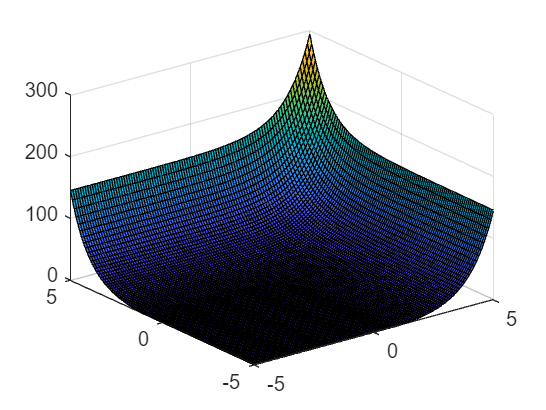

Z3 = reshape(f_max_exp_K3(points), [n n]);
Z6 = reshape(f_max_exp_K6(points), [n n]);

% 3D plot of the function
surf(x, y, Z3)

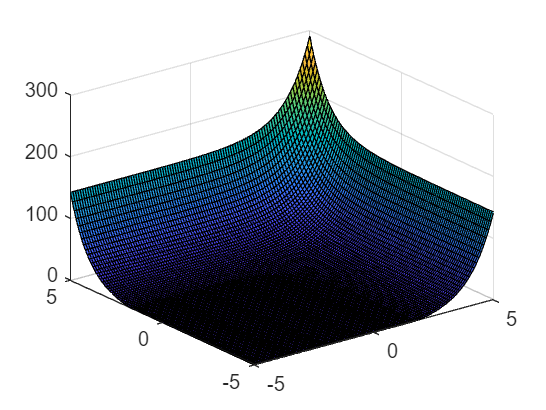

surf(x, y, Z6)

Now we estimate using Monte Carlo

estimates_K3 = zeros([1 M]);
variances_K3 = zeros([1 M]);
estimates_K6 = zeros([1 M]);
variances_K6 = zeros([1 M]);

M = 100;
for k=1:M
    rng(1)
    [estimates_K3(k), variances_K3(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K3, k);
    [estimates_K6(k), variances_K6(k)] = Monte_Carlo_HW1_Gaussian_Samples(@f_max_exp_K6, k);
end

y_values =    0.780732043500783


y_values =      0


y_values =    0.780732043500783                   0


y_values =      0     0


y_values =    0.780732043500783                   0                   0


y_values =      0     0     0


y_values =    0.780732043500783                   0                   0                   0


y_values =      0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0


y_values =                    0                   0                   0                   0   4.846392190637550


y_values =    0.780732043500783                   0                   0                   0                   0                   0


y_values =                    0                   0                   0   4.846392190637550                   0   5.829654807043811


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0


y_values =                    0                   0   4.846392190637550                   0   5.829654807043811                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0


y_values =                    0   4.846392190637550                   0   5.829654807043811                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    4.846392190637550                   0   5.829654807043811                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550


y_values =                    0   5.829654807043811                   0                   0                   0                   0                   0                   0   0.644878048789092                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0


y_values =    5.829654807043811                   0                   0                   0                   0                   0                   0   0.644878048789092                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811


y_values =                    0                   0                   0                   0                   0                   0   0.644878048789092                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0


y_values =                    0                   0                   0                   0                   0   0.644878048789092                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493


y_values =                    0                   0                   0                   0   0.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0


y_values =                    0                   0                   0   0.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054


y_values =                    0                   0   0.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0


y_values =                    0   0.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579


y_values =    0.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0


y_values =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0


y_values =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446


y_values =    0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0


y_values =                    0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283


y_values = 1×27
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×27
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0


y_values = 1×28
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×28
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0


y_values = 1×29
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×29
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0


y_values = 1×30
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×30
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×31
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×31
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×32
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×32
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×33
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×33
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×34
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×34
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×35
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×35
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×36
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×36
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×37
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×37
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938


y_values = 1×38
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×38
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0


y_values = 1×39
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×39
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0


y_values = 1×40
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×40
                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0


y_values = 1×41
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×41
                   0                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0


y_values = 1×42
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×42
                   0                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0


y_values = 1×43
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×43
                   0                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0


y_values = 1×44
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×44
                   0                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0


y_values = 1×45
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×45
                   0                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×46
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×46
                   0                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×47
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×47
                   0                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×48
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×48
                   0   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×49
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×49
   0.053061443371446                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974


y_values = 1×50
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×50
                   0   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0


y_values = 1×51
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×51
   2.755372284390283                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0


y_values = 1×52
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×52
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0


y_values = 1×53
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×53
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0


y_values = 1×54
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×54
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0


y_values = 1×55
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×55
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0


y_values = 1×56
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×56
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0


y_values = 1×57
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×57
                   0                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×58
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×58
                   0                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×59
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×59
                   0                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×60
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×60
                   0                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×61
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×61
                   0                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×62
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×62
                   0                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×63
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×63
                   0                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×64
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×64
                   0                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×65
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×65
                   0   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792


y_values = 1×66
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×66
   0.403442546546938                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0


y_values = 1×67
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×67
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0


y_values = 1×68
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×68
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882


y_values = 1×69
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×69
                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0


y_values = 1×70
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×70
                   0                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0


y_values = 1×71
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×71
                   0                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0


y_values = 1×72
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×72
                   0                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730


y_values = 1×73
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×73
                   0                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0


y_values = 1×74
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×74
                   0                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0


y_values = 1×75
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×75
                   0                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0


y_values = 1×76
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×76
                   0                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378


y_values = 1×77
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×77
                   0   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0


y_values = 1×78
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×78
   1.267437038595974                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0


y_values = 1×79
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×79
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0


y_values = 1×80
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×80
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0


y_values = 1×81
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×81
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0


y_values = 1×82
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×82
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217


y_values = 1×83
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×83
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0


y_values = 1×84
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×84
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0


y_values = 1×85
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×85
                   0                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0


y_values = 1×86
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×86
                   0                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0


y_values = 1×87
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×87
                   0                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0


y_values = 1×88
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×88
                   0                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813


y_values = 1×89
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×89
                   0                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0


y_values = 1×90
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×90
                   0                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0


y_values = 1×91
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×91
                   0                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0


y_values = 1×92
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×92
                   0                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0


y_values = 1×93
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×93
                   0   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0


y_values = 1×94
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×94
   1.233480853631792                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0


y_values = 1×95
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×95
                   0                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0


y_values = 1×96
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×96
                   0   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×97
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×97
   5.826637162578882                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×98
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×98
                   0                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×99
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×99
                   0                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×100
   0.780732043500783                   0                   0                   0                   0                   0                   0                   0                   0   7.846392190637550                   0   8.829654807043811                   0   1.722747147585493                   0   1.632111689223054                   0   1.731201785799579   3.644878048789092                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


y_values = 1×100
                   0   3.404602026609730                   0                   0                   0   8.105571335348378                   0                   0                   0                   0                   0   6.566496205606217                   0                   0                   0                   0                   0   0.307013807356813                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


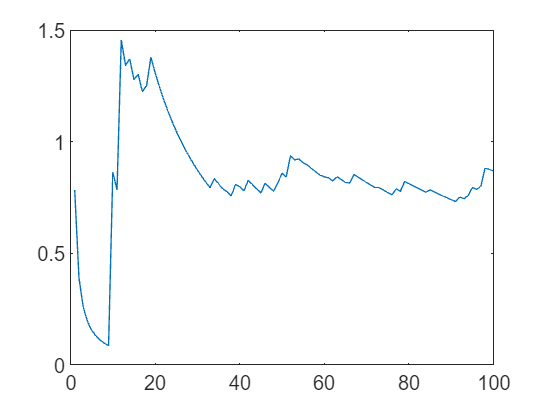


plot(1:M, estimates_K3)

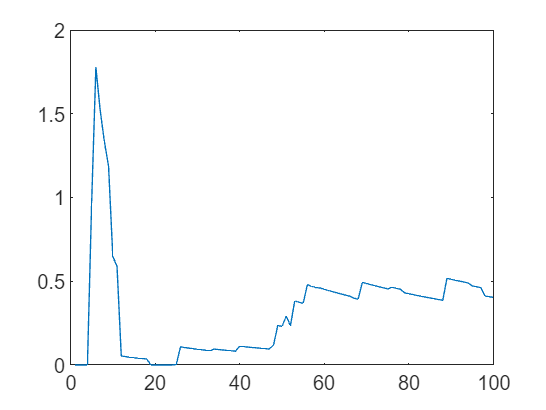

plot(1:M, estimates_K6)

Now we want to solve the problem


$$(\mu_1^\ast,\mu_2^\ast) = \text{argmax}_{x_1,x_2}\left(\max(e^{x_1}+e^{x_2}-K, 0)\cdot\rho_{x_1}(x_1)\cdot \rho_{x_2}(x_2)\right)$$


 where $\rho_{x_1}(x_1) = \frac{1}{\sqrt{2\pi}}e^{-\frac{1}{2}x^2}$. For that we follow the suggestion of looking at plots of the target function above.

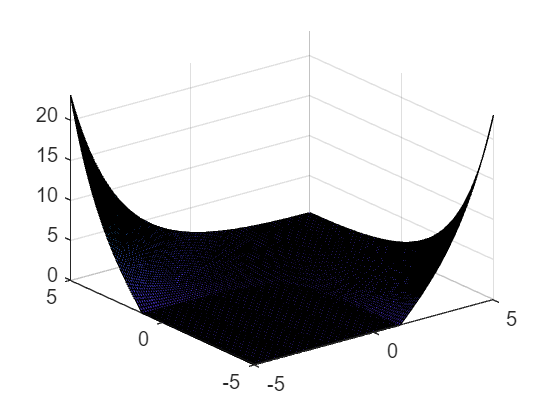

Z_K3 = reshape(targetfunction_K3(points), [n n]);
Z_K6 = reshape(targetfunction_K6(points), [n n]);

% 3D plot of the current example function
surf(x, y, Z_K3)

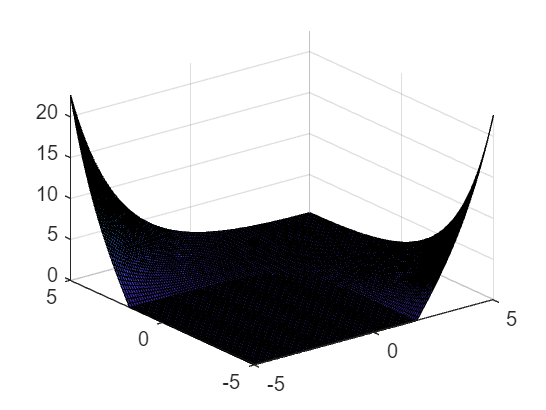

surf(x, y, Z_K6)

It seems like the optimal shift of the mean for importance sampling is a diagonal, meaning if we shift $X_1$ towards $+\infty$ we shift $X_2$ towards $-\infty$ in the same manner. Lets check some values of $(\mu_1^\ast,\mu_2^\ast)$

mu_1 = 5;
mu_2 = -mu_1;
M_IS = 100;

%Monte_Carlo_HW1_Gaussian_Samples_shifted(f_max_exp_K3, M, mu_1, mu_2);

sample1 = normrnd(mu_1, 1, [1, M_IS]);
sample2 = normrnd(mu_2, 1, [1, M_IS]);
samples = [sample1; sample2];
y_values = f_max_exp_K3(samples);
MC_est = 1/M_IS*sum(y_values)

MC_est =      3.436466387272084e+02



MC_var = (1/(M_IS-1))*sum((y_values - MC_est).^2)

MC_var =      4.155239634381135e+05
